# Eksamen E2021

Mathias Bruun Houmøller  -  202006837

format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)
% latex(expr)

## Opgave 1 

Mathias Bruun Houmøller  -  202006837

a)

Data indskrives

clear
m_L = 100; %kg
s_L = 0.75; % m
kA = 12000; %N/m
kB = 15000; %N/m
g = 9.81; %m/s^2

Bevægelsesligningen for lodet kan beskrives


$$x(t) = \frac{g \cdot t^2}{2}$$
 

Da start hastigheden er 0(frigjort fra hvile) og vi kan betragte loddet start position som 0, vi opstiller ligningen og solver for t hvor $x(t) = s_L$

syms t positive

x_eq = s_L == g * t^2 /2

$$x\_eq = \frac{3}{4}=\frac{981\,t^{2}}{200}$$

t_slut = solve(x_eq, t);
t_slut_ =vpa(t_slut,5)

$$t\_slut\_ = 0.39103$$

**Loddet rammer fjeder A efter 0,39 s**

**b)**

loddets hastighed findes ved at differentier bevægelsesligningen hvor vi får


$$v(t) = g \cdot t$$


Vi indsætter den fundne hastighed


v_slut = g * t_slut;
v_slut_ = vpa(v_slut, 4)

$$v\_slut\_ = 3.836$$

**Hastigheden af loddet når vi rammer fjederen er således **$3,84\ m/s$

c)

Vi finder energi i loddet ved lineær kinetisk energi som


$$T = \frac{1}{2}mv^2$$


Vi indsætter den fundne slut hastighed fra b)

T = 1/2 * m_L * v_slut^2;
T_ = vpa(T, 6)

$$T\_ = 735.75$$

**Vi får en energi i loddet på **$735,75\ J$

d)

linear momentum G findes ved at integreres 


$$F = m \cdot g$$
 

til


$$G = m\cdot g \cdot t = m \cdot v $$


Hvor start tiden t er 0, dermed får vi

G = m_L * g * t_slut;
G_ = vpa(G, 6)

$$G\_ = 383.601$$

**Vi får det lineær momentum til **$383,6\ kg\ m\ s^{-1}$   

**e)**

Vi opstiller vores koordinatsystem med 0 punkt i fjederens top før sammentrykning, positiv x retning er nedad. Det forstås som at loddet rammer fjederen og der ventes til systemet står helt stille.

syms x positive

Vi opstiller to ligninger og finder sammentrykningen ved ligevægt $F=0$

en for samentrykningen x = 0 til 0,1 og en for samentrykningen x= 0,1 til 0,4

x_final_eq = 0 == m_L*g - kA*x  

$$x\_final\_eq = 0=981-12000\,x$$

x_final = solve(x_final_eq, x);
x_final_ = vpa(x_final, 4)

$$x\_final\_ = 0.08175$$

**Vi ser at fjederen kun sammentrykkes 0,082 m og vi rører derfor ikke fjeder B**

**Dog kan der forkomme at fjeder b rammes efter sammenstødet inden ligevægt.**

Alternativt med energi ligningen få dybeste punkt fjederen trykkes ned når energien afsat af loddet er 0


$$V_L - V_A - V_B = 0$$
 

syms x positive

Højde lodet smides fra indgår i energien da 0 punktet er fjeder A's overflade.

h = x + 0.75 %m

$$h = x+\frac{3}{4}$$

V_L = m_L * g * h

$$V\_L = 981\,x+\frac{2943}{4}$$

V_A = 1/2 * kA * x^2 

$$V\_A = 6000\,x^{2}$$

Fjeder B's højde trækkes 0,1 fra da den rammes senere

V_B = 1/2 * kB * (x-0.1)^2 

$$V\_B = 7500\,{\left(x-\frac{1}{10}\right)}^{2}$$

Vi løser ligningen for x

S_eq = 0 == V_L - V_A - V_B

$$S\_eq = 0=981\,x-7500\,{\left(x-\frac{1}{10}\right)}^{2}-6000\,x^{2}+\frac{2943}{4}$$


S = solve(S_eq, x);
S_ = vpa(S, 5)

$$S\_ = 0.33145$$

**Vi får således at sammentrykningen er 0,33 m og altså et stykke nede i fjeder B**

## Opgave 2

Mathias Bruun Houmøller  -  202006837

a)

clear
q = 2 %kg/m

q =      2


g = -9.81 %m/s^2

g =         -9.81


L_AB = 1.5

L_AB =           1.5


L_BC = 1.5

L_BC =           1.5


L_CD = 1.5

L_CD =           1.5


**a)**

Længderne adderes sammen og ganges på masse pr længden

m_tot = (L_AB + L_BC + L_CD) * q

m_tot =      9


**Rammen vejer 9,0 kg**

**b) **

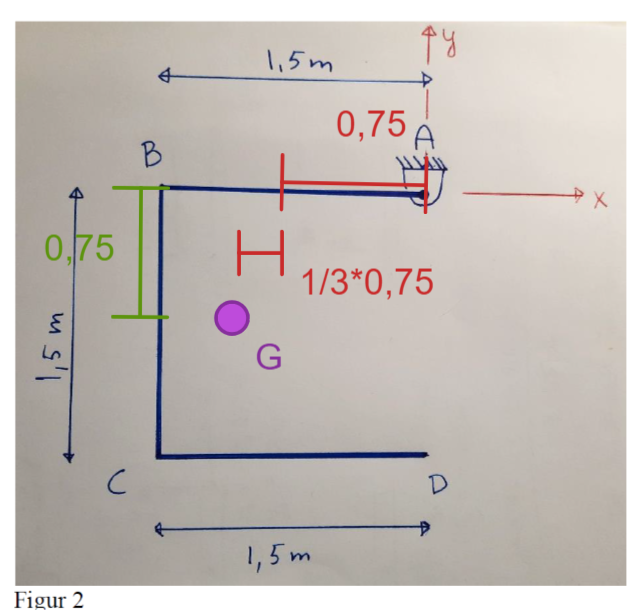

VI ser at de 3 stang elementer er ens

**x-retningen**

Her ligger AB og CD's centroider 0,75 m fra origo bidraget fra fra det sidste element bliver 1/3 af den totale masse og dermed "trækkes" tyngdepunktet 1/3 af den resterende længde ud af negativ x retning (0,75). 

x_G = -0.75 - 1/3 * 0.75

x_G =     -1


y-retningen

her er vægten lille lidt fordelt fra B til C vi får der med centroiden i 0,75

y_G = -0.75

y_G =         -0.75


Vi får nu Tyngdepunktets position til punktet G (1; 0,75) markeret med lilla

**MERE RIGTIGT SVAR**

Vi ligger ganger masse og afstand fra centroiden på hvert emne sammen 

fra x-aksen

L = 1.5; %m
M = q * L

M =      3


M_tot = 3 * M

M_tot =      9


Sx_AB = 0 * M

Sx_AB =      0


Sx_BC = -L/2 * M

Sx_BC =         -2.25


Sx_CD = -L * M

Sx_CD =          -4.5



x_G = (Sx_AB + Sx_BC + Sx_CD) / M_tot

x_G =         -0.75


fra y-aksen

Sy_AB = -L/2 * M

Sy_AB =         -2.25


Sy_BC = -L * M

Sy_BC =          -4.5


Sy_CD = -L/2 * M

Sy_CD =         -2.25



y_G = (Sy_AB + Sy_BC + Sy_CD) / M_tot

y_G =     -1


**Således får vi **$x_C = -0,75$** og **$y_C = -1,00$

**c)**

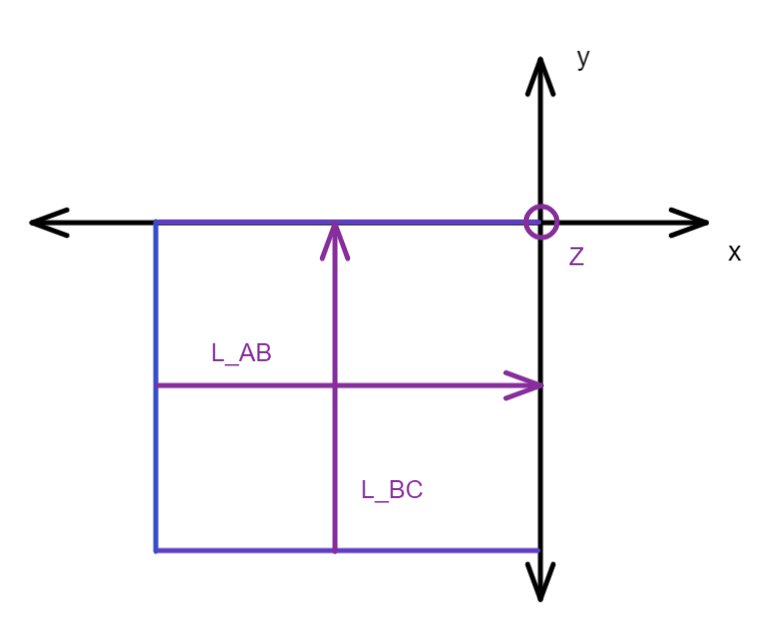

Det ses at der kun sker rotaion omkring z aksen

Masseinertimomentet om A findes ved at forskyde tyngdepunktet ind på enden af hver stang

BC forskydes længden L ind så den ligger på y-aksen

CD forskydes længden L op så den ligger på x-aksen

L = 1.5 %længden af hver stang

L =           1.5


M = q * L

M =      3



d_BC = L %forskydelsen af BC's tyngde punkt 

d_BC =           1.5



d_CD = L %forskydelsen af CD's tyngde punkt

d_CD =           1.5



stangAB_I_zz = 1/3 * M * L^2 %ligger op af rotations aksen

stangAB_I_zz =          2.25



stangBC_I_zz = 1/3 * M * L^2 + M*d_BC^2 % forskydes til rotations aksen

stangBC_I_zz =      9



stangCD_I_zz = 1/3 * M * L^2 + M*d_CD^2 % forskydes til rotations aksen

stangCD_I_zz =      9



disp('-----------------------------------------')

-----------------------------------------



%total inertimomentet er således
I_tot_zz = stangAB_I_zz + stangBC_I_zz + stangCD_I_zz

I_tot_zz =         20.25


Således for vi et inertimoment på 


$$I = 20,25\ kg\ m^2$$


**d)**

**FBD**

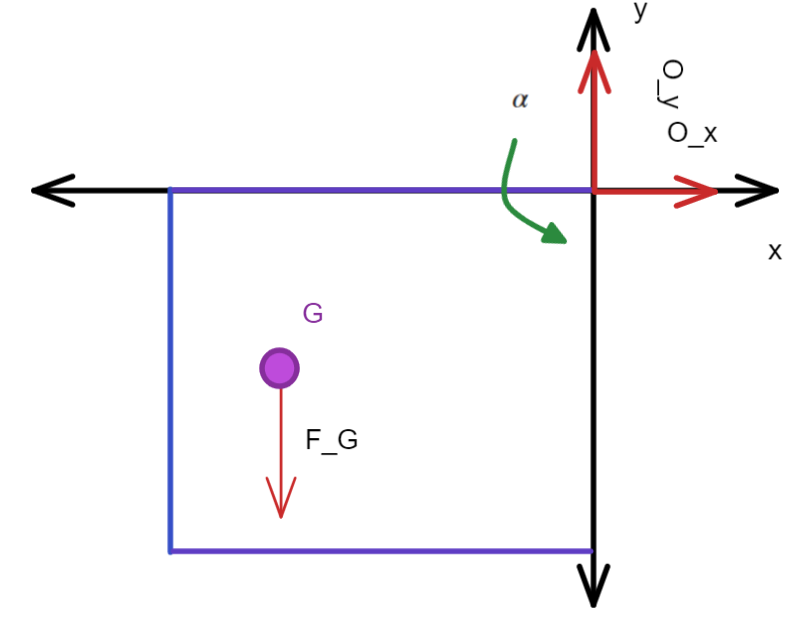

**KD**

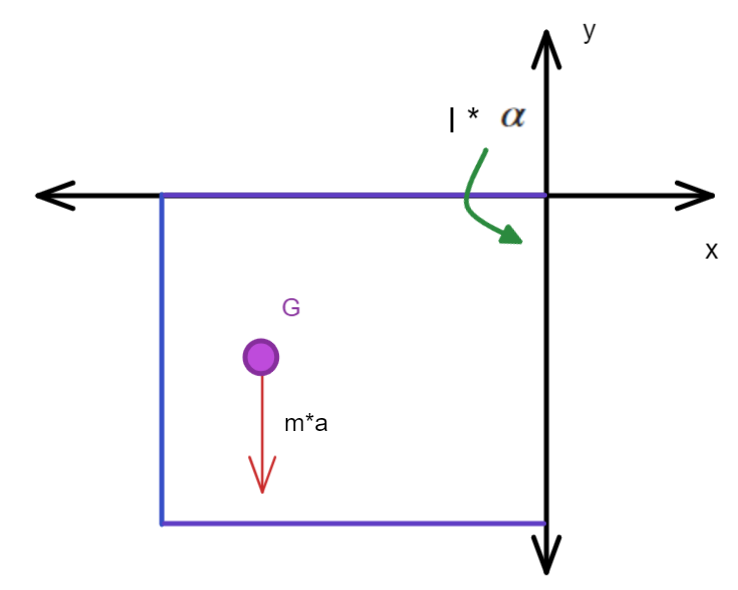

**e)**

Vinkelaccelrationen finde med momentligningen

Armen for tyngdepunktet moment er x_G og den trækker ned med tyngdekraften m * g

moment kan også beskrives som 


$$M = I \cdot \alpha$$
 

M = m_tot* g * x_G

M =        66.218


alpha = M/I_tot_zz

alpha =          3.27


Vinkelaccelerationen er såldes $\alpha = 4,36\ s^{-2}$

**f)**

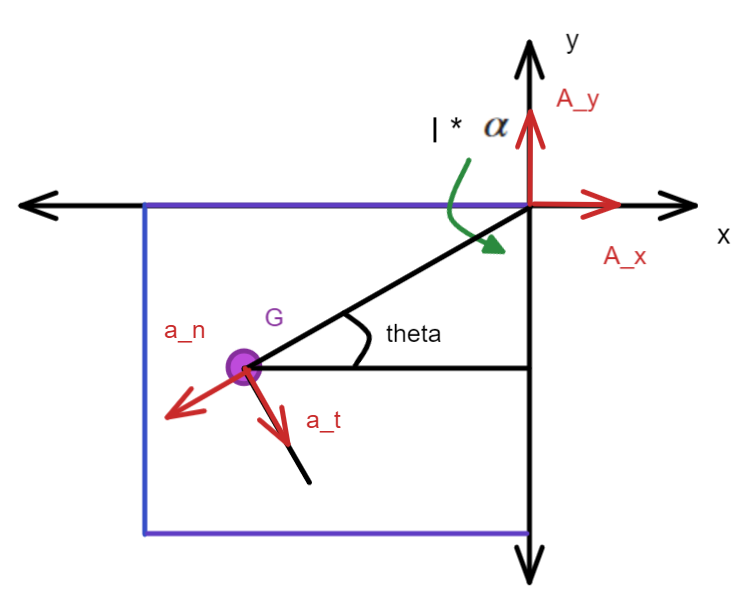

afstanden til tyngde punktet beskrives som

d = sqrt(x_G^2 + y_G^2)

d =          1.25


vinklen til x-aksen findes

theta = atand(y_G/x_G)

theta =         53.13


Den tangielle acceleration beskrives med $a_n = d * \alpha$

a_t = d * alpha

a_t =        4.0875


I dette punkt er der kun bidrag fra tangial kraften og vi finder nu $a_x$ og $a_y$ med $\theta$

a_x = a_t * cosd(theta)

a_x =        2.4525


a_y = -a_t * sind(theta)

a_y =         -3.27


Således får vi accelerations komposanterne

 
$$a_x = 4,36\ m\ s^{-2}$$



$$a_y = -3,27\ m\ s^{-2}$$


**g)**

M = q * L * 3

M =      9


A_x = a_x * M

A_x =        22.073


A_y = a_y * M - M*g

A_y =         58.86


% A_x = a_n * cos(theta) + a_t * cos(theta)
% A_y = a_n * sin(theta) + a_t * sin(theta)

% g) A_x = 29.43 N, A_y = 49.05 N


## Opgave 3

Mathias Bruun Houmøller  -  202006837

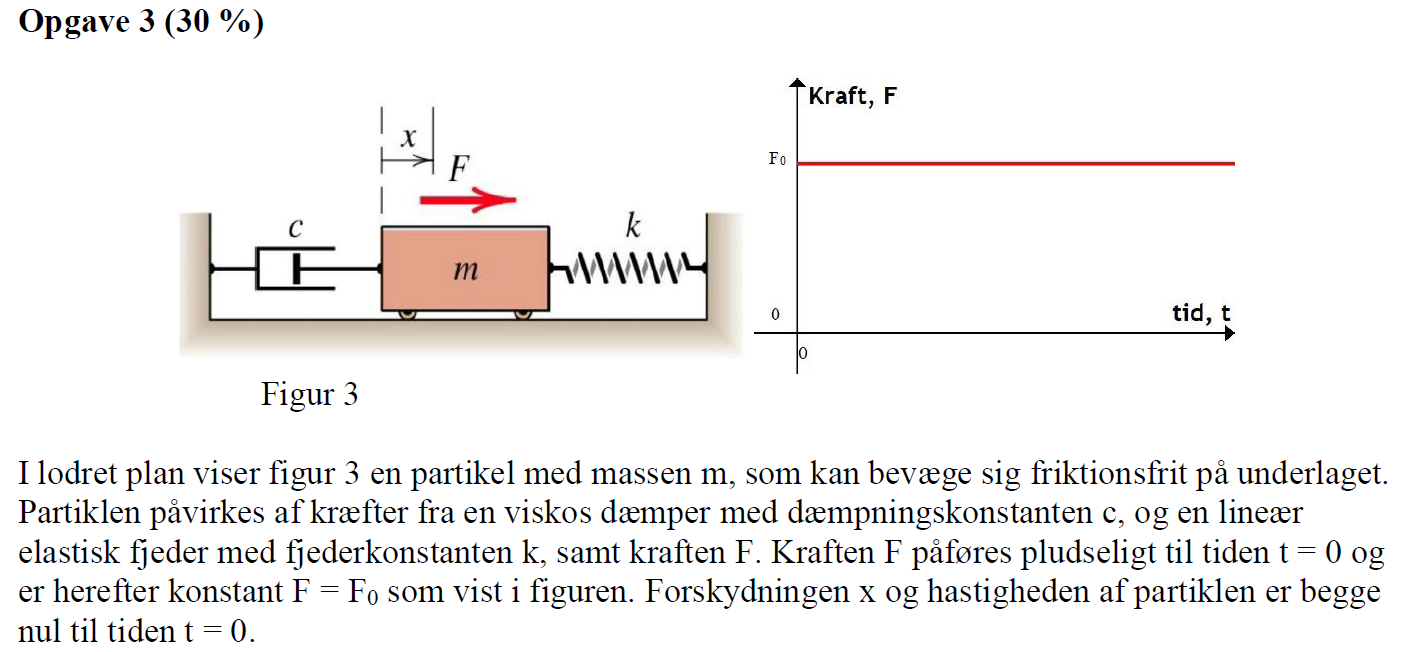

a)


$$\sum F_x = m\cdot\ddot x
\\
F_0 -c \dot x - kx = m\ddot x
\\
\ddot x + \frac{c}{m}\dot x + \frac{k}{m}x = \frac{F_0}{m} 
\\
\ddot x + 2\zeta\omega_n\dot x + \omega_n^2x = \frac{F_0}{m}$$



$$\ddot x + 2\zeta\omega_n\dot x + \omega_n^2x = 0$$


clear
% Data:
c = 10 %Ns/m

c =     10


k= 20 %N/m

k =     20


m=10 %kg

m =     10


F0=100 %N

F0 =    100


**b)**

w_n = sqrt(k/m) %egensvingningen

w_n =        1.4142


egenfrekvensen bliver således $\omega_n = 1,41\ s^{-1}$

**c)**

disp('Dæmpningsrationen findes')

Dæmpningsrationen findes


zeta = c/(2 * m * w_n) % viscous damping factor or damping ratio

zeta =       0.35355



if separateUnits(zeta) < 1
    disp('systemet er underdamped')
elseif separateUnits(zeta) == 1
    disp('systemet er critical damped')
else
    disp('systemet er overdamped')
end

systemet er underdamped



$$\zeta = 0,35$$


$\zeta < 1$ og systemet er dermed underdæmpede.

**d)**

Finder den naturlige dæmpnings frekvens

w_d = w_n*sqrt(1-zeta^2) % damped natrual freqancy

w_d =        1.3229


**e)**


$$\ddot x + 2\zeta\omega_n\dot x + \omega_n^2x = \frac{F_0}{m}$$



$$x(t) = \frac{F_0}{k} \\
x'(t) = 0 \\
x''(t) = 0$$


vi får nu


$$\omega_n^2 \frac{F_0}{k} = \frac{F_0}{m} \\
\omega_n^2 = \frac{k}{m} \\
\frac{F_0}{m} = \frac{F_0}{m} $$


## f)

clear
% Opgave data
c = 10;
k = 20;
m = 10;
F0 = 100;
t0 = 0; t1 = 10;

syms x1
x0 = F0/k; % N/(N/m) = m
% Formler

wn1 = sqrt(k/m);
zeta1 = c/(2*m*wn1);
wd1 = wn1*sqrt(1 - zeta1^2);

% Diff ligning
syms x(t) zeta lambda t A wn k m C wd psi x

x_plac = C*exp(-zeta*wn*t) * sin(wd*t + psi)  == x0;
% Til t0
x_plac_numt0 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t0]),3);
% til t1;
x_plac_numt1 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t1]),3);

x_vel = diff(x_plac, t) == 0;
% til t0;
x_vel_numt0 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t0]),3);
% til t1;
x_vel_numt1 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t1]),3);


eqst0 = [x_vel_numt0, x_plac_numt0];
eqst1 = [x_vel_numt1, x_plac_numt1];
unks = [C, psi];

solt0 = solve(eqst0, unks);

psi = solt0.psi % Den største absolutte værdi skal vælges for psi og C

$$psi = \left(\begin{array}{c} 1.2094292028846515477720268022864\\ -1.9321634507051416906906165809931 \end{array}\right)$$

C = solt0.C   %

$$C = \left(\begin{array}{c} 5.3452248382556340499300035741502\\ -5.3452248382556340499300035741502 \end{array}\right)$$

 
C = vpa(solt0.C(1),4)

$$C = 5.345$$

psi = vpa(solt0.psi(2),4)

$$psi = -1.932$$


x_plac = vpa(C*exp(-zeta1*wn1*t1) * sin(wd1*t1 + psi),3)

$$x\_plac = -0.0344$$

syms func(t)
xp = x0;

func(t) = C*exp(-zeta1*wn1*t) * sin(wd1*t + psi) + xp;

fplot(func(t), [0,10]), xlabel("Tid [s]"), ylabel("Forskydning [m]")
hold on
fplot(xp, [0,10]), grid()
hold off

En anden form af 8.11 er benyttet, hvor C (samling af de "normale" A konstanter), og faseforskydningen $\psi$ er brugt.

Det giver:


$$C = 5,345$$



$$\psi = 1,206$$


Og en forskydning efter 10 sekunder på


$$x(10) = 0,0344m$$



clear
% Opgave data
c = 10;
k = 20;
m = 10;
F0 = 100;
t0 = 0; t1 = 10;

syms x1
x0 = F0/k; % N/(N/m) = m
% Formler

wn1 = sqrt(k/m);
zeta1 = c/(2*m*wn1);
wd1 = wn1*sqrt(1 - zeta1^2);

% Diff ligning
syms x(t) zeta lambda t A wn k m C wd psi x A1 A2

x_plac = (A1*cos(wd*t) + A2*sin(wd*t))*exp(-zeta*wn*t) + x0 == 0

$$x\_plac = {\mathrm{e}}^{-t\,\mathrm{wn}\,\zeta }\,\left(A_{1}\,\cos\left(t\,\mathrm{wd}\right)+A_{2}\,\sin\left(t\,\mathrm{wd}\right)\right)+5=0$$

% Til t0
x_plac_numt0 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t0]),3);
% til t1;
x_plac_numt1 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t1]),3);

x_vel = diff(x_plac, t) == 0;
% til t0;
x_vel_numt0 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t0]),3);
% til t1;
x_vel_numt1 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t1]),3);


eqst0 = [x_vel_numt0, x_plac_numt0];
eqst1 = [x_vel_numt1, x_plac_numt1];
unks = [A1, A2];

solt0 = solve(eqst0, unks);
solt1 = solve(eqst1, unks);

A1 = vpa(max(solt0.A1),5)

$$A1 = -5.0$$

A2 = vpa(max(solt0.A2),5)

$$A2 = -1.8898$$


x_plac = vpa((A1*cos(wd1*t1) + A2*sin(wd1*t1))*exp(-zeta1*wn1*t1), 3)

$$x\_plac = -0.0344$$

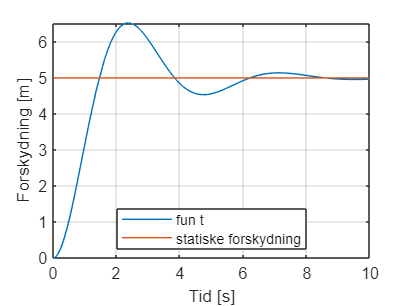

syms func(t)
xp = x0;

func(t) = (A1*cos(wd1*t) + A2*sin(wd1*t))*exp(-zeta1*wn1*t) + xp;

fplot(func(t), [0,10], "displayname", "fun t"), xlabel("Tid [s]"), ylabel("Forskydning [m]")
hold on
fplot(xp, [0,10], "displayname", "statiske forskydning"),  legend('location','best'), grid(),
hold off